files = ["data20", "data-20", "data40", "data-40", "data60", "data-60", "data80", "data-80", "data100", "data-100"]; %
voltages = [20, -20, 40, -40, 60, -60, 80, -80, 100, -100]; 
k_all = [];
Tm_all = [];

## Plotting for omega(t)


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>



Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


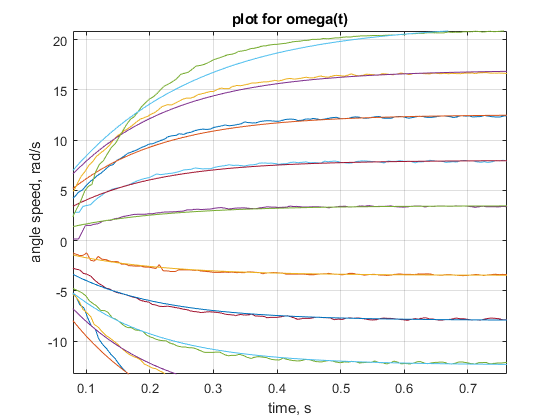

for i=1:10
    data = readmatrix(files(i));
    time=data(:,1);
    U = voltages(i);
    angle=data(:,2)*pi/180;
    omega=data(:,3)*pi/180;
    
    title("plot for omega(t)")
    figure(1)
    plot(time,omega);
    xlabel("time, s")
    ylabel("angle speed, rad/s")
    grid on
    xlim([0 1]);
    
    hold on 
    % approximation - let's take....
    lol0 = [0.1; 0.006];
    % given voltage in percents
    U_pr = 100;
    % 0(t) = ...
    func = @(lol, time) U_pr*lol(1)*(1 - exp(-time/lol(2)));

    % Nonlinear least-squares solver %
    solver = lsqcurvefit(func,lol0,time,omega);
    k = solver(1);
    Tm = solver(2);
  
    time_apr = 0:0.01:1;
    theta = U_pr*k*(1 - exp(-time_apr/Tm));
    plot(time_apr,theta);
    hold on
    
    % plotting for omega(t)
 
 
   
end